# Practical 7

## Question Form

Phthalic Anhydride (PA) is industrially produced by the oxidation of the o-xylene on $V_2 O_5 -{\textrm{TiO}}_2$  catalyst. The o-xylene diluted in air is fed to a multi tubular fixed bed reactor cooled by the circulation of a molten salts. Details of the configuration, catalysts, and operating conditions are given below. The  reaction network is given by the following three reactions: 


$$\begin{array}{l}
C_6 H_4 {\left({\textrm{CH}}_3 \right)}_2 +3O_2 \to C_6 H_4 {\left(\textrm{CO}\right)}_2 O+3H_2 O\;\;\left(1\right)\;\;\;\;\;\;\;\;\Delta H=-1285409\;\frac{\textrm{kJ}}{\textrm{kmol}}\\
C_6 H_4 {\left({\textrm{CH}}_3 \right)}_2 +10\ldotp 5O_2 \to 8{\textrm{CO}}_2 +5H_2 O\;\;\;\;\;\left(2\right)\;\;\;\;\;\;\;\;\;\;\;\;\Delta H=-4564000\;\frac{\textrm{kJ}}{\textrm{kmol}}\\
C_6 H_4 {\left(\textrm{CO}\right)}_2 O++7\ldotp 5O_2 \to 8{\textrm{CO}}_2 +2H_2 O\;\;\;\;\left(3\right)\;\;\;\;\;\;\;\;\;\;\Delta H=-327859\;\frac{\textrm{kJ}}{\textrm{kmol}}
\end{array}$$


The system can be considered a mixture of ideal gases. Adopting a 1D pseudo-homogeneous model with the heat transfer computed through the Dixon-Specchia correlation, assess:

- the number of tubes needed considering the constraints reported in the data.  

- the thermal profile along the tube.  

- the conversion of $C_6 H_4 {\left({\textrm{CH}}_3 \right)}_2$ and the selectivity of $C_6 H_4 {\left(\textrm{CO}\right)}_2 O$ along the tube.  

What is a possible solution to improve the productivity per tube reaching a reactor design with less than 9000 tubes?

## Theory

The overal heat transfer coefficient is written as follows:


$$\frac{1}{U}=\frac{1}{\alpha_{\int } }+\frac{t}{\lambda_{\textrm{tube}} }\ldotp \frac{A_{\int } }{A_{\log } }+\frac{1}{\alpha_{\textrm{ext}} }\ldotp \frac{A_{\int } }{A_{\textrm{ext}} }$$


Since we want to study on 1D psuodo homogeneous model, the $\alpha_{\int }$ term is so important for us. It consists of 2 parameters called $\lambda_{\textrm{eff}\;} ,\alpha_w$. The $\alpha_w$ consists of two contributions, Static and Dynamics. The $\alpha_{\int }$ expressed as follows:


$$\begin{array}{l}
\frac{1}{\alpha_{\int } }=\frac{1}{\alpha_w }+\frac{d_{\textrm{tube}} }{\lambda_{{\textrm{eff}}_R } }\ldotp \frac{1}{\beta }=\frac{1}{\alpha_w }\left\lbrack 1+\frac{\alpha_w d_T }{\lambda_{{\textrm{eff}}_R } }\ldotp \beta \right\rbrack \\
\textrm{Bi}=\frac{\alpha_w d_T }{\lambda_{{\textrm{eff}}_R } }\\
\beta =6\frac{\left(\textrm{Bi}+4\right)}{\left(\textrm{Bi}+3\right)}
\end{array}$$


## Parameters and Initialization

close all, clear all, clc
global Stoichiometry deltaH mw SpecificHeatP Viscosity0 ...
    TubeDiameter CatalystDensity ...
    VoidFraction MoltenSaltsTemperature G ParticleDiameter NS NR lambda0 ...
    lambda_cat ReactorLength TubeThickness lambdaTube ExternalHeatCoefficient

Stoichiometry=[0 -3 -1 1 +3 0
               0 -10.5 -1 0 5 8
               0 -7.5 0 -1 2 8];

deltaH=[-1285409 -4564000 -3278591]; %kJ/kmol
%-species:
mw=[28 32 106.16 148.12 18 44]; %kg/kmol
SpecificHeatP=0.992; %kJ/kg/K
Viscosity0=2.95e-5; %Pa*s
NS = 6;
NR = 3;
%-Reactor:
TubeDiameter=0.0254; %m
ParticleDiameter=0.005; %m
ReactorLength=3; %m
CatalystDensity=2100; %kg/m3
DiameterRatio=TubeDiameter/ParticleDiameter;
VoidFraction=0.363+0.35*(exp(-0.39*DiameterRatio));
ExternalHeatCoefficient=700; %W/m2/K
TubeThickness=0.0012; %m
lambdaTube=20; %W/m/K 
lambda0=4.78e-2; % W/m/K
lambda_cat=1.5; %W/m/K

## Operating Conditions

MoltenSaltsTemperature=335+273.15; %K
FeedTemperature=MoltenSaltsTemperature;
G=4900; %kg/m2/h
oXylToAirRatio=0.0215;
n_in=[0.79 0.21 oXylToAirRatio 0 0 0]; %moles
ntot_in = sum(n_in);
for i = 1:NS
    MolarFractionIN(i) = n_in(i)/ntot_in;
end
FeedPressure=1.3; %bar

basis_calc=1; %kmol
for i=1:NS
    mass(i)=MolarFractionIN(i)*basis_calc*mw(i); %kg
end
mtot = sum(mass);

for i = 1:NS
    MassFractionIN(i) = mass(i)/mtot;
end

## Prepare and solve ODE system.

% [t,y]=ode15s('pfr_pseudo_hom',[0:0.01:ReactorLength], ...
%     [MassFractionIN FeedTemperature FeedPressure]);
%1st_bed: 0 to L/2
CatalystDensitySupplier = CatalystDensity;
dilution_bed1=0.55;
CatalystDensity=CatalystDensitySupplier*dilution_bed1;
[t1,y1]=ode15s('pfr_pseudo_hom',[0:0.01:ReactorLength/2], ...
    [MassFractionIN FeedTemperature FeedPressure]);

%2nd_bed: L/2 to L
dilution_bed2=1;
CatalystDensity=CatalystDensitySupplier*dilution_bed2;
[t2,y2]=ode15s('pfr_pseudo_hom',[ReactorLength/2:0.01:ReactorLength], ...
    y1(end,:));

t=cat(1,t1,t2);
y=cat(1,y1,y2);

## Post Processing

NP=length(t);
Across=pi*TubeDiameter^2/4; %m2

for j=1:NP
    for i=1:NS
        n(j,i)=G*Across*y(j,i)/mw(i); % kmol/h
    end
    MolarFraction(j,:)=n(j,:)./sum(n(j,:));
end

%conversion o-xylene:
for j=1:NP
    conv_o_xyl(j)=(n(1,3)-n(j,3))/(n(1,3));
end

%selectivity to PA:
for j=1:NP
    sel_PA(j)=n(j,4)/(n(1,3)-n(j,3)+1e-12);
end

%yield:
for j=1:NP
    yield(j)=conv_o_xyl(j)*sel_PA(j);
end

%productivity: kg_PA/ut in the tube
for j=1:NP
    productivity_tube(j)=yield(j)*n(1,3)*mw(4);
end

target = 8000; % Ton/year
n_tubes = target*1e3/(365*24)*1/productivity_tube(end);
disp("number of tubes: "+ n_tubes)

number of tubes: 8933.2864


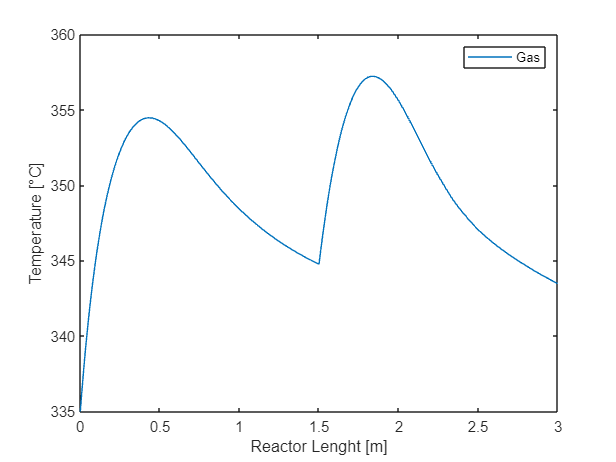

figure(1)
plot(t,y(:,7)-273.15)
hold on

xlabel('Reactor Lenght [m]')
ylabel('Temperature [°C]')
legend('Gas')

## Jalal's Notes

As mentioned in the question we want to produce PA from the oxidation of o-xylene in a catalytic bed reactor. As requested by the question I use the 1D heterogeneous model with the heat transfer computed through the Dixon-Specchia correlation. In this model, the presence of reaction and transport in parallel could create the occurrence of gradients between the catalyst and the gas phase. So, due to the difference in the concentration of species and the temperature in the gas phase and on the catalyst surface, we need two equation for concentration gradients and two for the temperature gradients. We only need one equation for pressure. With these 5 equations and their boundary conditions that we wrote, we could determine the axial evolution of temperature and concentration for both the gas and the solid phase. To get the number of tubes needed for this question, we could calculate the productivity for one tube and with the goal that we want from this unit which is 8000 ton/year we could get the total number of tubes needed. To get the productivity of tube we need to know conversion, selectivity and yield in the reactor. Also, there is a limit on the system that the maximum pressure drop per meter is not be more than 0.1 bar/m. According to the equations that we have and the data which are given we could modify them and write them based on G=4900 kg/h/m2. We also need to get the values for their boundary condition. We know that at z=0 T=T0=335 C, P=P0=P_ outlet + delta P=1.3 bar, and for mass fraction in the inlet we need to calculate it. First, we need to identify the species which are 6. Then, according to question we are diluting the o-x with air so the inlet moles are only N2, O-X, and O2 [0.79 0.013 0.21 0 0 0]. With having these moles, we could calculate the molar fraction. Now with multiplying them with their molecular weight we could get the mass of every species and at the end calculate the inlet mass fraction. Now, according to the equation that we have, we need to identify the av, epsi, ki, h, U, pg, stochiometric coefficients, reaction rates, delta_ H, and superficial velocity. To identify each of these parameters we have some related equations and data that we could use. We should really be careful for the units when we are converting it.  For the mass gas density we could use the assumption according to the question that we have an ideal gas and calculate it (density mass gas=(P/R*T)*10^-3*mw_ average). The superficial velocity could be calculate it from the inlet flow rate(V=G/density mass gas/3600). Now, we need to find the stochiometric coefficients and modify the reaction rate. Stochiometric coefficients are achievable from the three reaction scheme that we have. The reaction rate should be written in terms of total pressure(bar) and mol fraction of species on the catalyst surface. Now, we only have five equations and five unknowns and could get the change in mass fraction of any species in the reactor, the thermal profile, the conversion, selectivity and yield. The parameters that we could change to reduce the number of tubes are inlet pressure and temperature, flow rate, o-x concentration, and external temperature. With increasing the pressure, the gas density and reaction rate increases. This will enhance the productivity and reduce the number of tubes. But it cannot reduce it under 9000 tubes, because the reaction rate which is exothermic is increasing in the reactor, and as we only have one hot spot, the thermal run away happen and the reactor design collapse. The same thing happens when we increase the other parameters. The best procedure is to dilute the catalytic bed and divide it into two sections according to the first hot spot that we have making two hot spots in the reactor. The first section should be diluted to decrease the reaction happening their and the second one only have the catalyst to make the reaction increase and make the second hot spot. Now we could easily increase the pressure or o-x concentration without reaching thermal runway and exceed the limit of the previous design.